# System Integration and Test Simulation

Configure a simulation that uses the following:

- Truth Locations - Field-collected ADSB data recorded with an RTL-SDR

- Detections and Sensor-based Tracks:

- Active radar (fusionRadarSensor)

- ADSB data (gpsSensor and ADSBReceiver)

- TrackFuser for C2 level tracks

- OSPA Metric, trackAssignmentMetrics, and errorMetrics for track accuracy analysis

close all force; clear all; addpath('../HelperFunctions/')

Import truth location of aircraft and prerecorded sensor data

mapOrigin = [42.39423231362 -70.95934958874 0];
load('TruthData.mat'); % Load Truth Trajectories
load('SensorData.mat'); % Load Pre-recorded Sensor Data

## Configure Simulation

### Setup Scenario

Scenario Creation includes configuring the Active Radar Sensor

truncatedStopTime = 60; % Limit Simulation time (s)
[scenario, mapViewer, activeRadarData] = helperCreateScenario(tuningData,mapOrigin,sensorData,truncatedStopTime);
%snapshot(mapViewer); % Only supported in MATLAB Desktop

### Configure Radar Tracker

[tracker,activeRadarSpec,targetSpec] = helperCreateTracker(scenario);

### Configure Secondary Sensor

Add ADSB for secondary target detection

Define Accuracy parameters for the gps sensor and assign ADSB transponder a

horAccuracy = 30;   % meters (NACp = 9)
vertAccuracy = 45;  % meters (NACp = 9)
velAccuracy = 0.6;  % m/s (NACv = 3)

## **Step 1 - Configure the gpsSensor to be used for ADSB**

**Directions:**

Assign an instance of 'gpsSensor' to the variable 'gps'

Use 'gpsSensor' function with the following name-value pairs to configure the gpsSensor to simulate ADSB accuracie:

- Set 'PositionInputFormat' to **'Geodetic'**

- Set 'HorizontalPositionAccuracy' to **horAccuracy**, the variable defined above

- Set 'VerticalPositionAccuracy' to **vertAccuracy**, the variable defined above

- Set 'VelocityAccuracy' to **velAccuracy**, the variable defined above

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc gpsSensor" in the Command Window to find the documentation page for this function
gps = gpsSensor('PositionInputFormat','Geodetic',...
    'HorizontalPositionAccuracy',horAccuracy,...
    'VerticalPositionAccuracy',vertAccuracy,'VelocityAccuracy',velAccuracy);

Leverage the provided helper function to store GPS transponder in a structure.

transponderStruct = helperCreateTX(scenario, gps);

### Configure ADSB Receiver for SSR

adsbRx = adsbReceiver('ReceiverIndex',2);
adsbRange = 2e5; % m

### Configure Track Fuser

You fuse radar tracks with ADS-B tracks obtained from the ADS-B receiver. To do this, you configure a central `trackFuser` object.

Define Process Noise for Fuser

procNoiseHorz = 3*targetSpec{1}.MaxHorizontalAcceleration^2/3;
procNoiseVert = 3*targetSpec{1}.MaxVerticalAcceleration^2/3;
fuseProcNoise = blkdiag(procNoiseHorz,procNoiseHorz,procNoiseVert);

Instantiate Fuser

fuser = trackFuser('FuserIndex',3,'MaxNumSources',2,...
    "AssignmentThreshold",[150 200],...
    "StateFusion",'Intersection',... 
    'StateFusionParameters','trace',...
    'ProcessNoise',fuseProcNoise, ...
    'ConfirmationThreshold',[5 7],...
    'DeletionThreshold', [5 8],...
    'FuseCoasted',true);

### Configure Metrics

ospa = trackOSPAMetric('CutoffDistance',500,'Distance','posabserr');
errorMetrics = trackErrorMetrics;
assignmentMetrics = trackAssignmentMetrics(...
    'AssignmentDistance','posabserr',...
    'DivergenceDistance','posabserr',...
    'DivergenceThreshold',50,...
    'AssignmentThreshold',50);

## Run Simulation

Run simulation fusing Radar Tracks with ADSB Tracks

numStepsToRun = numel(activeRadarData);
a1 = tic;
towerPos = scenario.Platforms{1};
stationaryIDs = [1, 2];  % Omit stationary platforms

for ind = 1:numStepsToRun
    advance(scenario);

    % Define Current Simulation Time
    time = scenario.SimulationTime;

    % Preallocate
    adsbTracks     = objectTrack.empty;
    adsbTracksNED = objectTrack.empty;
    radarTracks    = objectTrack.empty;
    fusedTracks    = objectTrack.empty;

    % Plot Radar Coverage
    covcon = coverageConfig(scenario);
    plotCoverage(mapViewer,covcon,"ECEF")

    % Plot Truth positions
    truePosePlot = platformPoses(scenario);
    plotPlatform(mapViewer, truePosePlot, 'ECEF');

    % Plot Radar Detections
    helperPlotActiveRadarData(mapViewer, activeRadarSpec, activeRadarData(ind));
    
    % Generate ADSB Messages with Range-Based ADSB Dropout
    clear adsbMessages
    adsbMessages = generateADSBMessages(scenario,transponderStruct,time,mapOrigin,adsbRange);

    % Only call ADSB Receive if messages exist at this Timestep
    if ~isempty(adsbMessages)
        adsbTracks = adsbRx(adsbMessages, time);
        adsbTracks = helperEnsureTimeAndParams(adsbTracks, time, helperEcefParams());
        % Convert ADSB Tracks to NED
        for i = 1:length(adsbTracks)
            adsbTracksNED(i) = helperEcef2nedTrack(adsbTracks(i),mapOrigin);
        end
    else
        adsbTracks = objectTrack.empty;
    end
    
    % Generate Radar Tracks
    radarTracksStruct = trackingAlgorithm_mex({activeRadarData(ind)},targetSpec,activeRadarSpec);
    radarTracks = helperConvertToObjectTrack(radarTracksStruct);
    radarTracks = helperEnsureTimeAndParams(radarTracks, time, helperNedParams(mapOrigin));

    % Fusion
    if isLocked(fuser) || ~isempty([adsbTracksNED';radarTracks])
        fusedTracks = fuser([adsbTracksNED';radarTracks], time);
    end

    % Plot all tracks
    mapViewer = helperPlotTracks(3,ind,mapViewer,scenario, adsbTracksNED,radarTracks,fusedTracks);

    drawnow;

    % Collect Metrics
    truePoseNED = targetPoses(towerPos);
    truthsForMetrics{ind} = truePoseNED(~ismember([truePoseNED.PlatformID], stationaryIDs));
    adsbTrackLog{ind} = adsbTracksNED;
    radarTrackLog{ind} = radarTracks;
    fusedTrackLog{ind} = fusedTracks;

    % Fused Track Metrics
    [trackAssignmentSummary(ind), truthAssignmentSummary(ind)] = assignmentMetrics(fusedTracks, truthsForMetrics{ind});
    [assignedTrackIDs, assignedTruthIDs] = currentAssignment(assignmentMetrics);
    [posRMSE(ind), velRMSE(ind), posANEES(ind), velANEES(ind)] = errorMetrics(fusedTracks, assignedTrackIDs, truthsForMetrics{ind}, assignedTruthIDs);
    trackError{ind} = cumulativeTrackMetrics(errorMetrics);
    truthError{ind} = cumulativeTruthMetrics(errorMetrics);
    assignedTruthIDsPerTime{ind} = assignedTruthIDs;
end
fprintf('Simulation complete (%.1f s)\n', toc(a1));

Phase 1 complete (65.1 s).  Check the globe viewer.


% snapshot(mapViewer); % Only supported in MATLAB Desktop

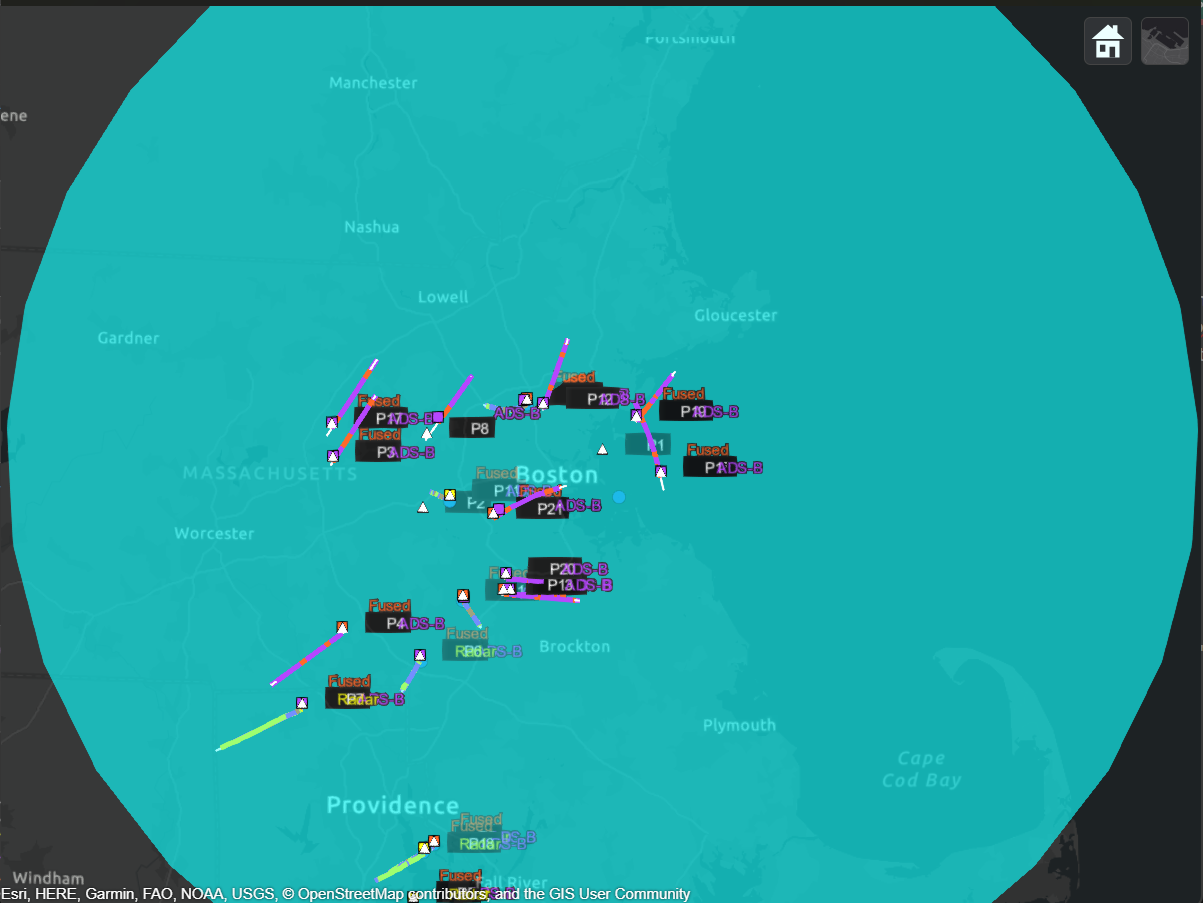

Change camera point of view to zoom in on radar FOV

cameraPos = 1.0e+03 *[0.0420   -0.0717    5.1059];
campos(mapViewer,cameraPos(1),cameraPos(2),cameraPos(3));
cameraOri = [79.3398   -8.6789    0.0141];
camorient(mapViewer,cameraOri);

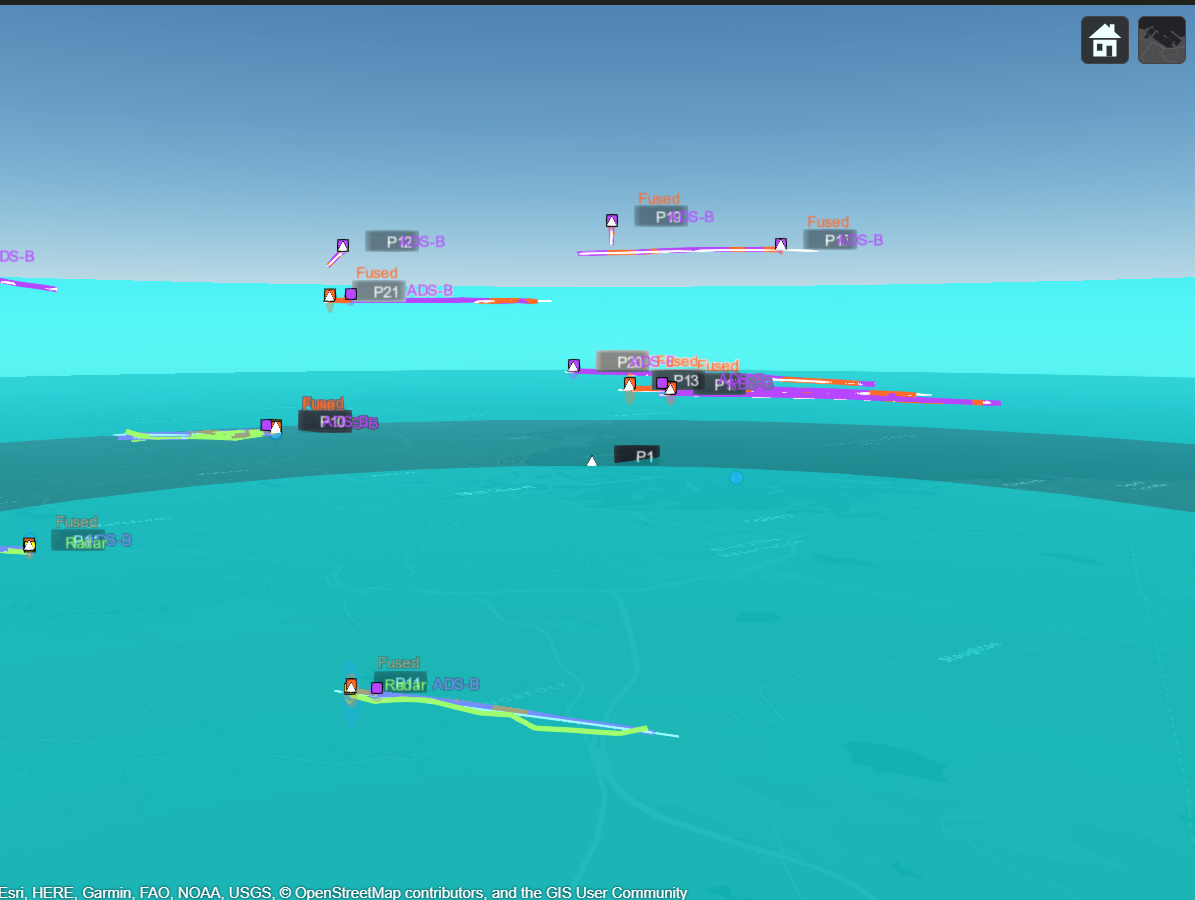

### Visualize Metrics

Run the below helper function that captures and plots the OSPA metric.  You should see that the fused tracks show a more smooth OSPA value often below the ADSB tracks, while the ADSB tracks are much noisier partly due to the ADSB dropout.

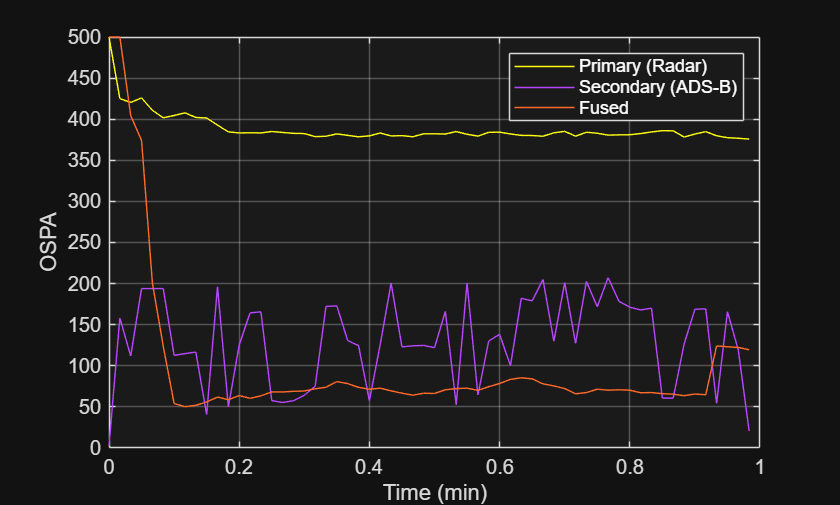

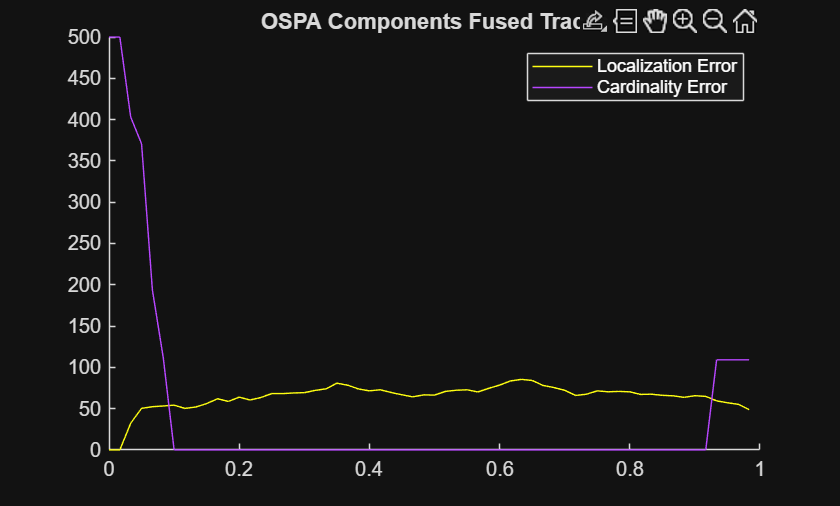

[radarospa,adsbospa,fusedospa] = helperCollectOSPAMetricsAndPlot(ospa,truthsForMetrics,radarTrackLog,adsbTrackLog,fusedTrackLog);

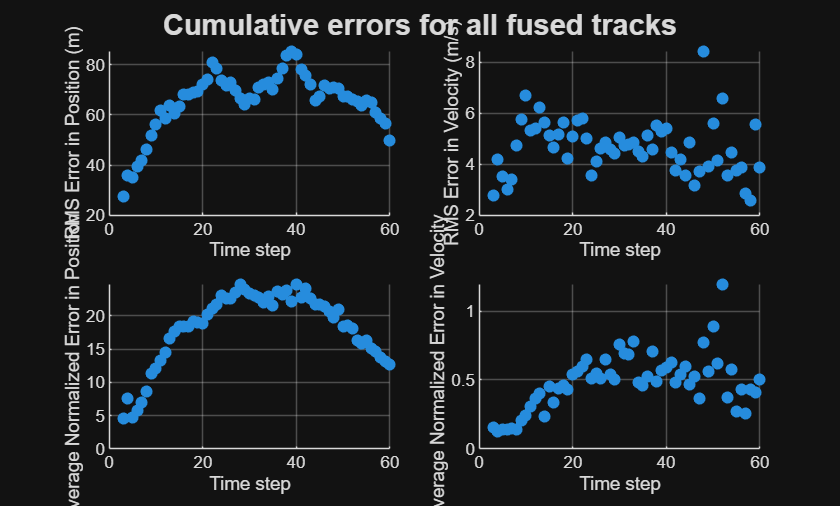

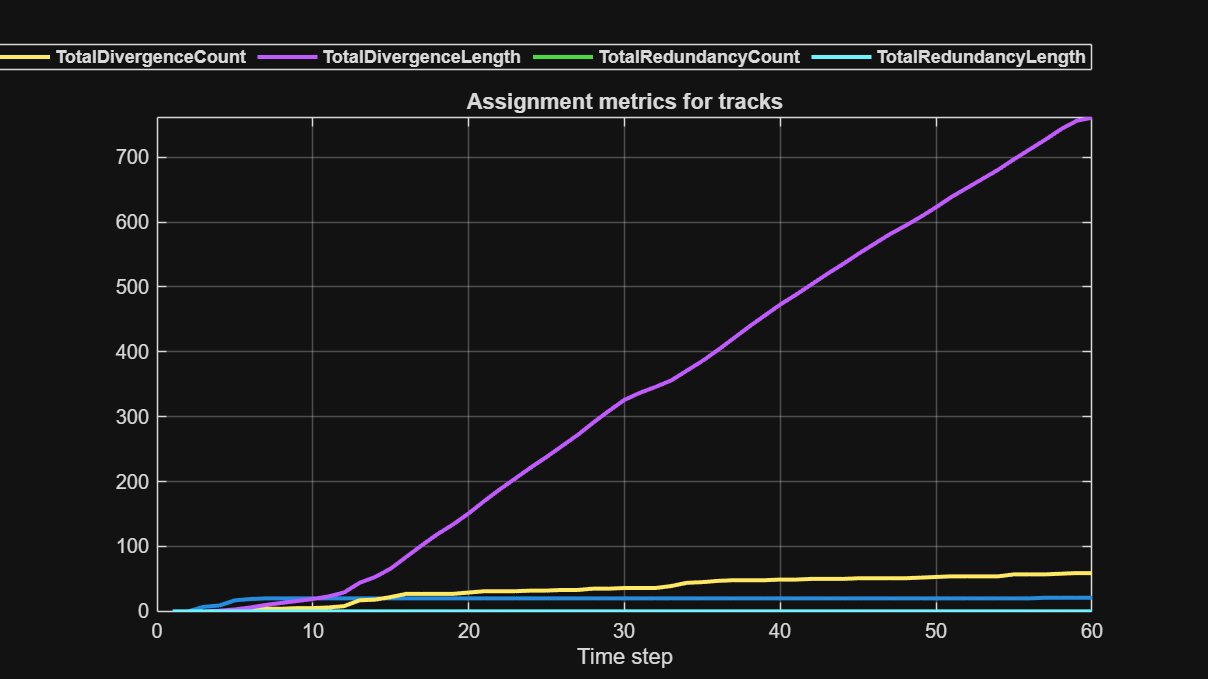

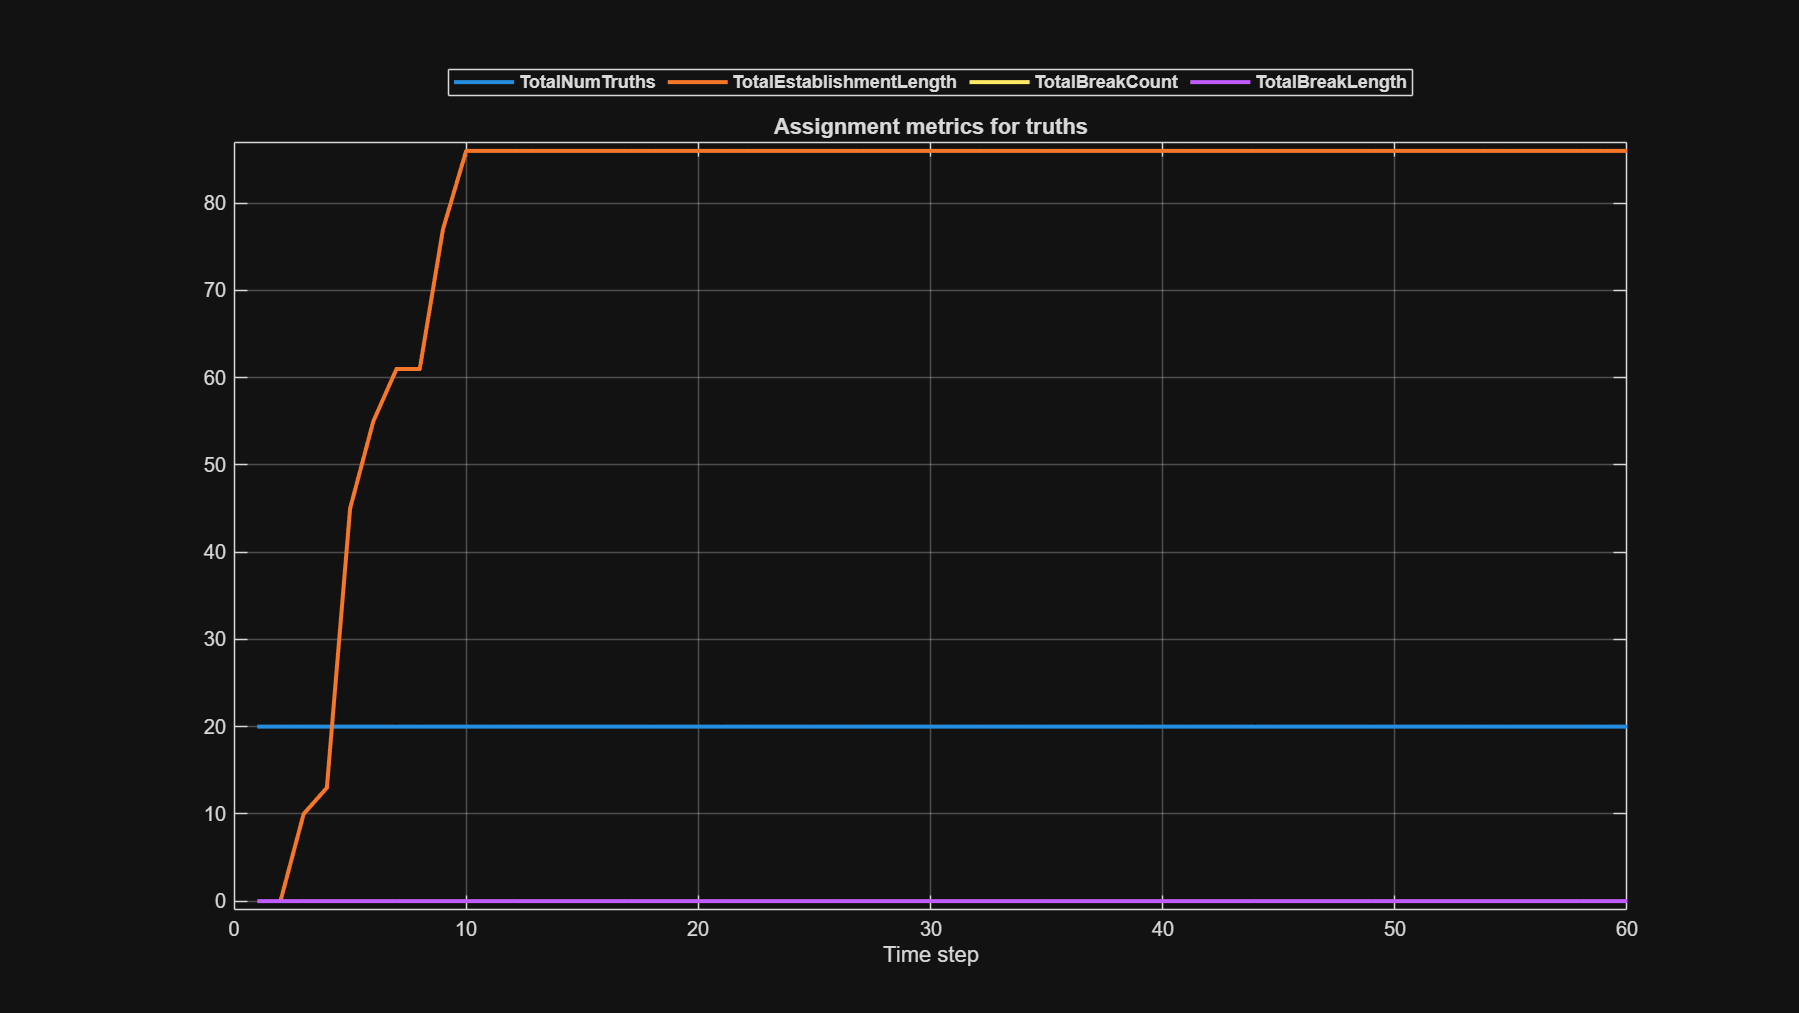

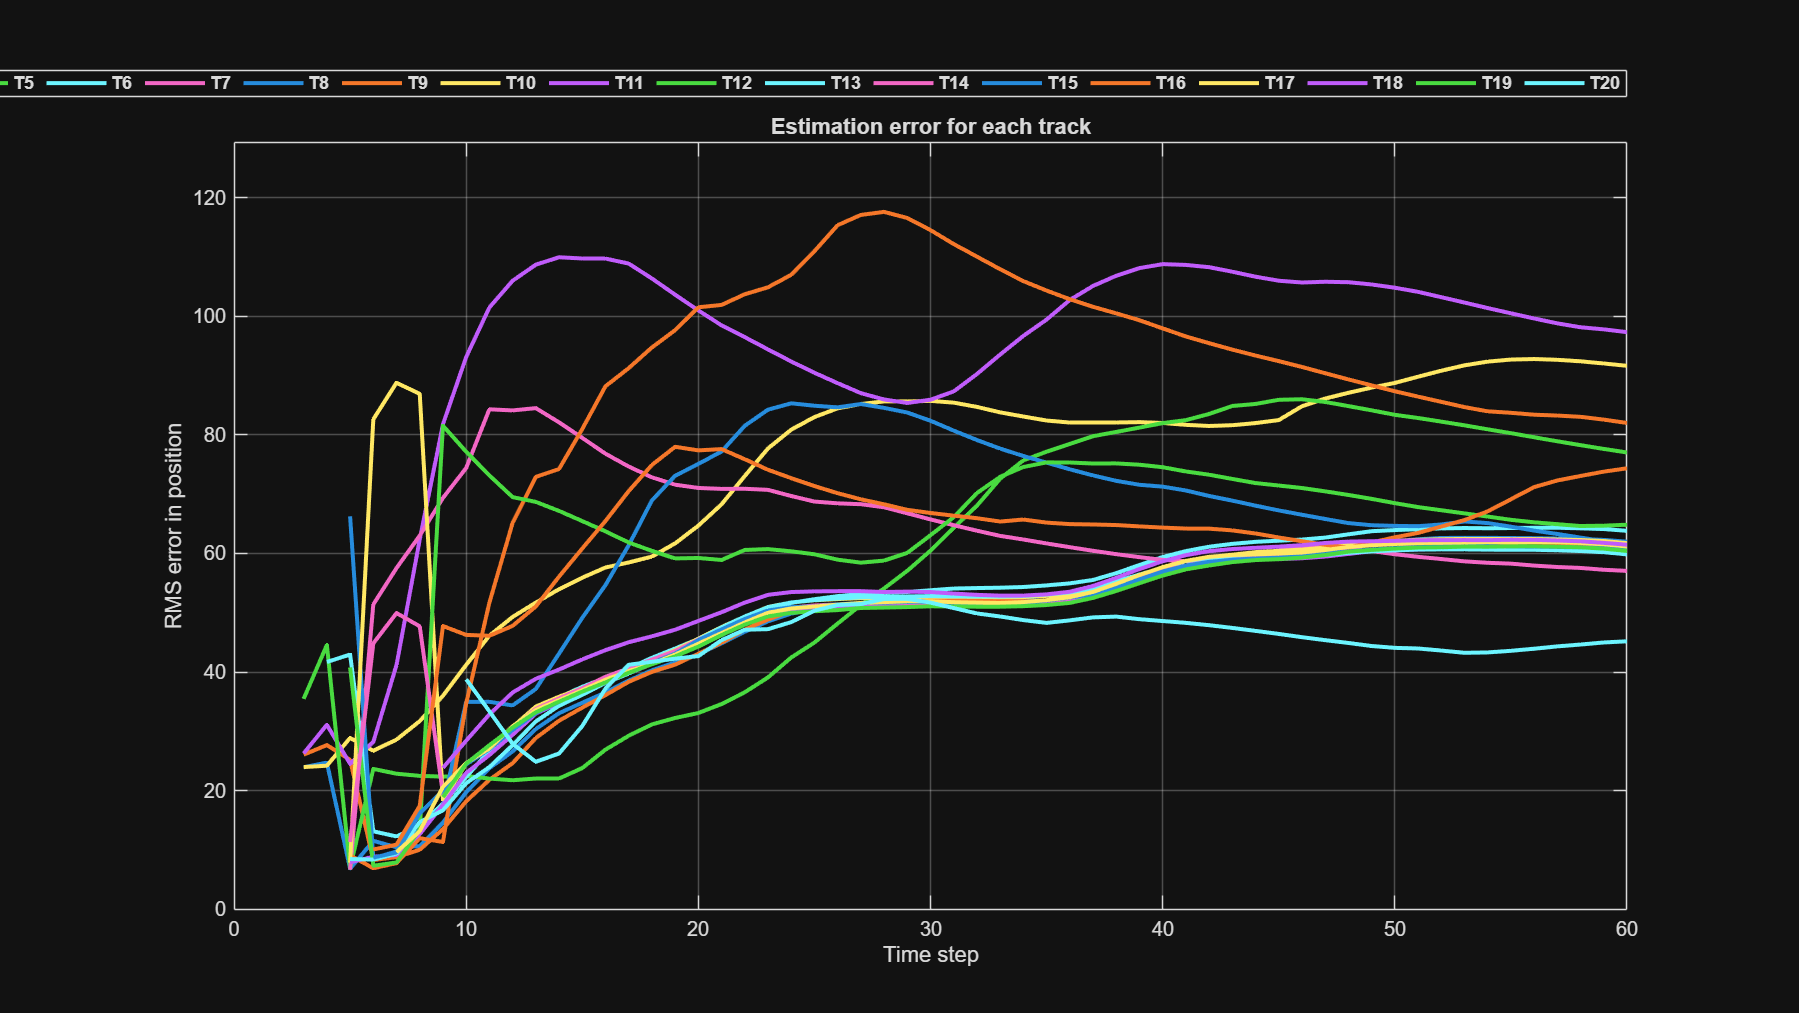

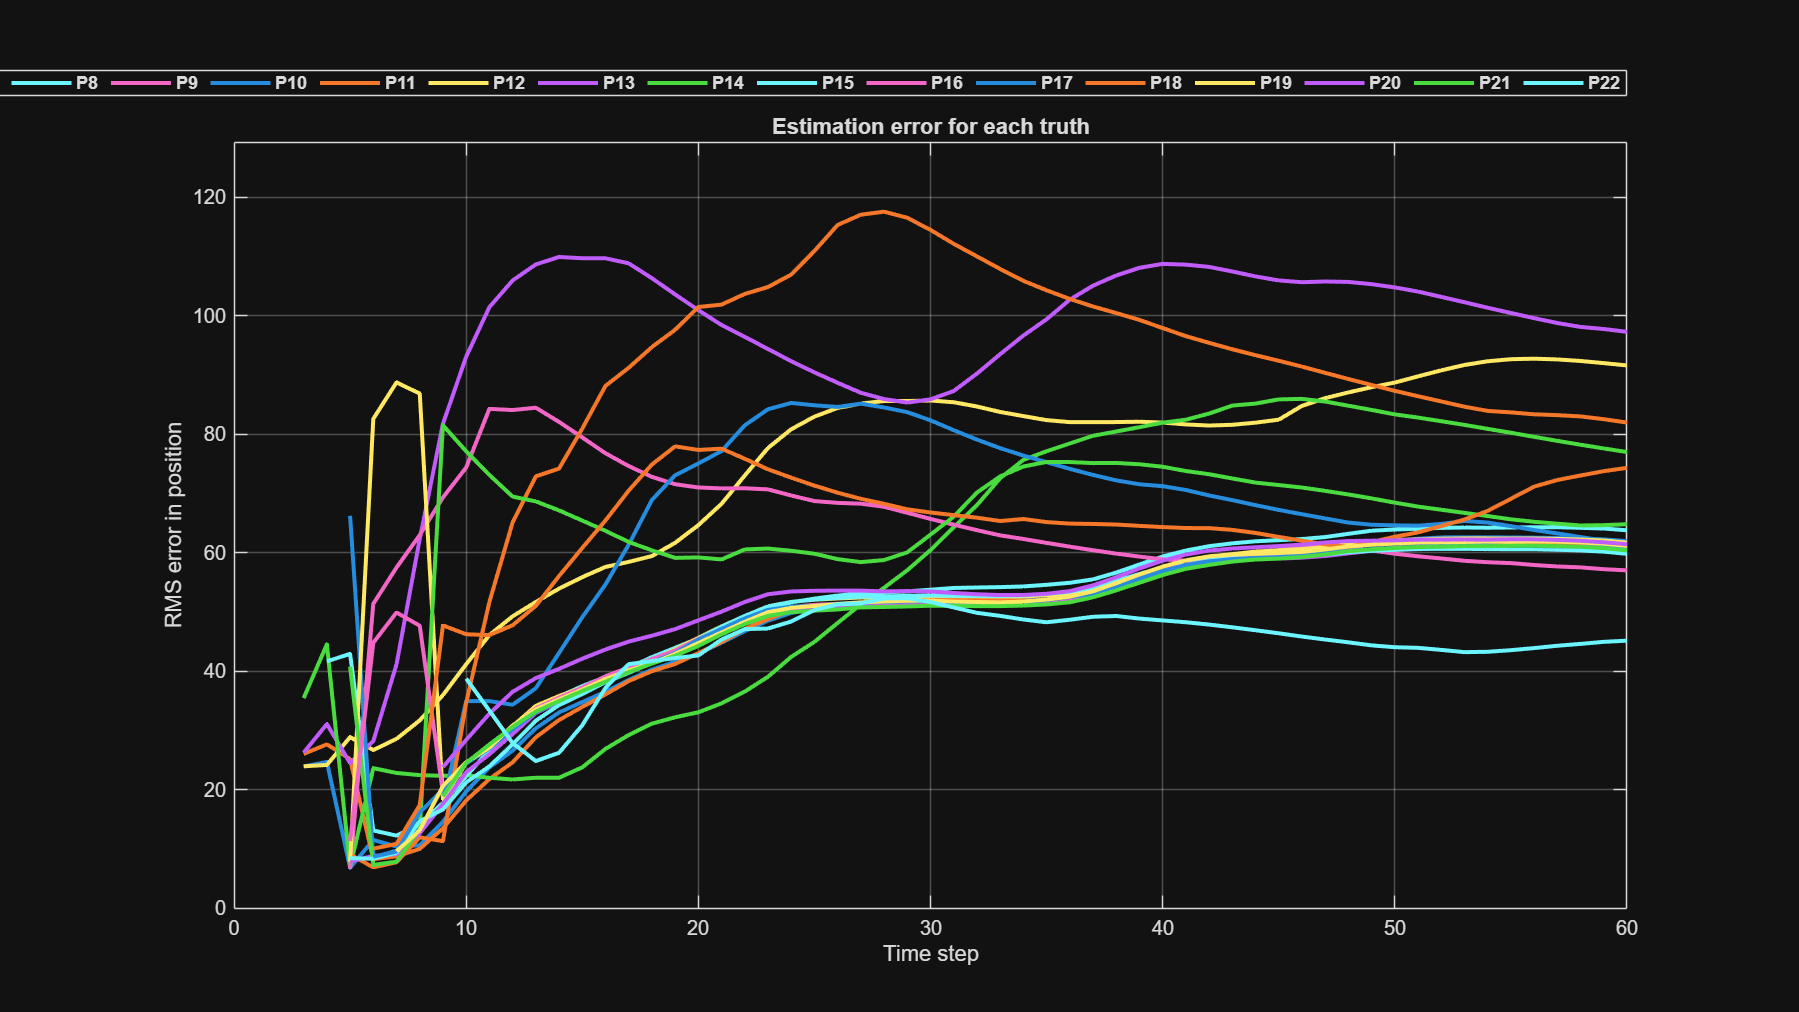

helperPlotRMS(posRMSE,velRMSE,posANEES,velANEES)

## BONUS:

Consider changing the ADSB dropout rates (PDropClose and PDropFar) in the "generateADSBMessages" function below, then rerunning the simulation. You should see that the ADSB and fused tracks change depending on these values.

function templateADSBMessage = generateTemplateADSBMessage
templateADSBMessage = struct('ICAO', 'MW2020',...
    'Time', '',...
    'Category','',...
    'Callsign','',...
    'Latitude',NaN,...
    'Longitude',NaN,...
    'Altitude',NaN,...
    'Veast',NaN,...
    'Vnorth',NaN,...
    'ClimbRate',NaN,...
    'Heading',NaN,...
    'NACPosition', NaN,...
    'GeometricVerticalAccuracy',NaN,...
    'NACVelocity',NaN);
end

function cartDistance = ADSBTargetRange(stationsLLA, pos) %cartDistance
cartDistance = fusion.internal.frames.lla2ecef(stationsLLA) - fusion.internal.frames.lla2ecef(pos);
%flag = any(vecnorm(cartDistance,2,2) < range);
end

function adsbMessages = generateADSBMessages(scenario,transponderStruct,time,mapOrigin,adsbRange)
adsbMessages = generateTemplateADSBMessage;
adsbMessages(1)=[]; % Clear Values from structure

for i = 3:numel(scenario.Platforms) % omit Stationary Towers
    poseStruct = pose(scenario.Platforms{i},'CoordinateSystem','Geodetic');
    poseStruct.PlatformID = scenario.Platforms{i}.PlatformID;
    truePoseGPS(i) = poseStruct;

    position = truePoseGPS(i).Position;
    velocity = truePoseGPS(i).Velocity;

    % Confirm Position Values exist
    isValid = all(~isnan(position));

    % Augment PDrop according to range
    PDropClose = 0.02;   % 5% dropout at close range
    PDropFar = 0.3;      % 30% dropout at max range
    cartDistance = ADSBTargetRange(mapOrigin, position);
    range_m = norm(cartDistance);
    rangeFactor = range_m / adsbRange;
    actualPDrop  = PDropClose + (PDropFar - PDropClose) * rangeFactor;
    keepMsg = rand >= actualPDrop;

    if isValid && keepMsg
        msg = transponderStruct(i-2).adsbTx(position,velocity);
        msg.Time = time;
        adsbMessages = [adsbMessages; msg];
    end
end

end

function [mapViewer,scenario,tracker,adsbRx,fuser,transponderStruct] = helperResetAll(mapViewer,scenario,tracker,adsbRx,fuser,transponderStruct)
% Reset for Phase 1
if exist("mapViewer")
    clear(mapViewer);
end
restart(scenario);
release(tracker);
reset(adsbRx);
reset(fuser)

for i = 1:length(scenario.Platforms)-2
    reset(transponderStruct(i).adsbTx);
end
end